% This simulation has been mostly inspired by Steve Brunton
clear all, close all, clc

m = 4;   % pend mass
M = 5;   % cart mass
L = 3;   % pend length
g = 10;  % gravity
d = .5;   % Friction force

## open loop first (we have no controllers yet)

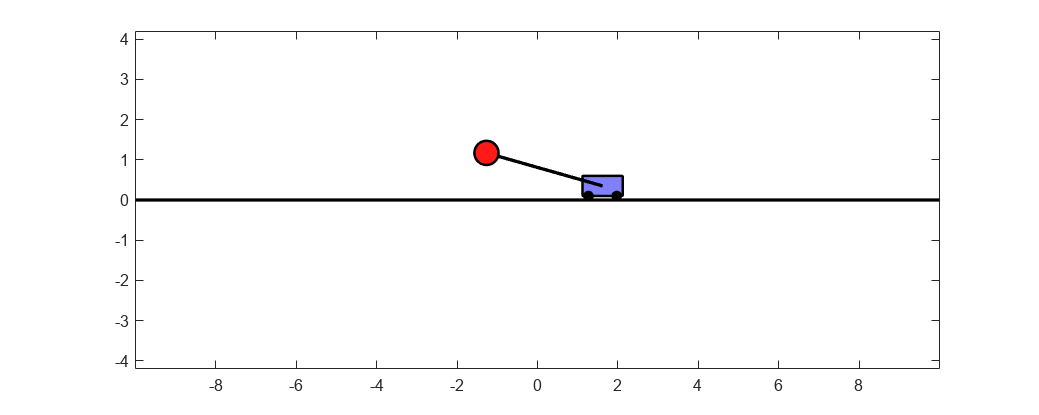

% define the time span from zero to 10 second with time speps
%tspan = linspace(0,20,1200);% write your code here;
tspan = 0:.0004:3.7;
 
% add initial conditions when pendulum is at 160 degrees

th_i = 160*pi/180;

y0 = [ 0; 0; th_i; 0]'; % write your code here;

[t,y] = ode45(@(t,y)pendcart_StateSpace(y,m,M,L,g,d,0),tspan,y0);


for k=1:100:length(t)
    drawpend(y(k,:),m,M,L);
end


% return

## Closed loop (in this part we add controller to the system)

% Step 1: Having a state spce equations we should able to create A abd B matrix
A=  [0, 1,   0,   0;
     0, 0, m*g/M, 0;
     0, 0,   0,   1;
     0, 0, (m+M)*g/(M*L), 0]

A =      0     1     0     0
     0     0     8     0
     0     0     0     1
     0     0     6     0


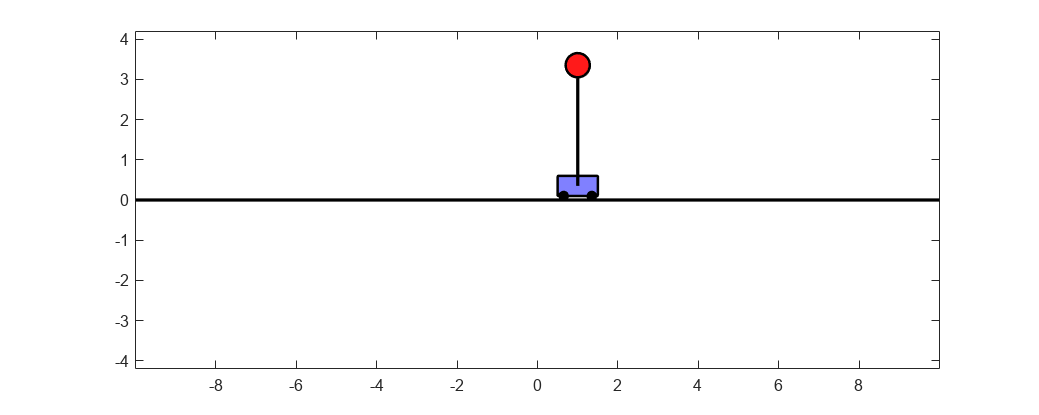


B=  [  0;
      1/M;
       0;
     1/(L*M)];

% Calculate the eigenvalue of the system and see if the system is stable or
% not
pole_locations = eig(A);

% Step 2: controllability: We want to know if the system is controlbale
rank(ctrb(A,B));

% Step 3: Pole placement
p_eigs=[-5, -6, -7, -8];
%p_eigs=[-.5, -1.5, -2, -2.5];
% step 4: calculating controller gain
% write your code here
K=place(A,B,p_eigs);

% Step 5: define the desired output (input)
r= [1;0;pi;0]; % write your code here;
tspan = 0:.0004:3.7;
[t,y] = ode45(@(t,y)pendcart_StateSpace(y,m,M,L,g,d,-K*(y-r)),tspan,y0);
% 
for k=1:100:length(t)
    drawpend(y(k,:),m,M,L);
end

% function drawpend(state,m,M,L)
% x = state(1);
% th = state(3);
% 
% % dimensions
% W = 1*sqrt(M/5);  % cart width
% H = .5*sqrt(M/5); % cart height
% wr = .2;          % wheel radius
% mr = .3*sqrt(m);  % mass radius
% 
% % positions
% y = wr/2+H/2; % cart vertical position
% pendx = x + L*sin(th);
% pendy = y - L*cos(th);
% 
% plot([-5*L, 5*L],[0 0],'k','LineWidth',2), hold on
% rectangle('Position',[x-W/2,y-H/2,W,H],'Curvature',.1,'FaceColor',[.5 0.5 1],'LineWidth',1.5); % Draw cart
% rectangle('Position',[x-.9*W/2,0,wr,wr],'Curvature',1,'FaceColor',[0 0 0],'LineWidth',1.5); % Draw wheel
% rectangle('Position',[x+.9*W/2-wr,0,wr,wr],'Curvature',1,'FaceColor',[0 0 0],'LineWidth',1.5); % Draw wheel
% plot([x pendx],[y pendy],'k','LineWidth',2); % Draw pendulum
% rectangle('Position',[pendx-mr/2,pendy-mr/2,mr,mr],'Curvature',1,'FaceColor',[1 0.1 .1],'LineWidth',1.5);
% 
% axis([-L-2*mr L+2*mr -L-2*mr L+2*mr]);
% axis equal
% axis();
% set(gcf,'Position',[100 100 1000 400]);
% drawnow, hold off
% end